# INTERPOLACJA

## WPŁYW UWARUNKOWANIA MACIERZY INTERPOLACYJNEJ NA EFEKT INTERPOLACJI

W algebrze o nieskończonej dokładności wszystkie rodzaje baz wielomianowych - wielomiany naturalne, Lagrange'a czy Newtona wyprodukują taką samą funkcję interpolującą i rodzaj zastosowanej bazy funkcji nie ma znaczenia.

Sytuacja ma się jednak odmiennie w przypadku obliczania funkcji interpolującej numerycznie na komputerze. Skoro uzyskanie rozwiązania naszego problemu wymaga rozwiązania układu równań liniowych, to wpływ na rozwiązanie ma uwarunkowanie tego układu równań. 

Przypomnijmy jednak czym jest w istocie uwarunkowanie numeryczne układu równań. Wyrażamy je za pomocą współczynnika uwarunkowania macierz ***A*** układu równań. Im większa wartość przyjmuje ten wskaźnik tym większym błędem będzie obarczony wynik ze względu na nieuniknione istnienie błędów w reprezentacji wartości liczbowych zawartych w macierzy ***A*** oraz wektorze ***b*** układu równań. 

Typowo jest tak, że współczynniki uwarunkowania rosną wraz z wymiarem macierzy ***A*** (ilością równań w układzie równań) choć nie jest to regułą. Dzieje się tak na pewno w pewnych postaciach macierzy ***A*** np. postaci Vandermonda.

Spróbujmy zobrazować sobie ten efekt zobrazować:

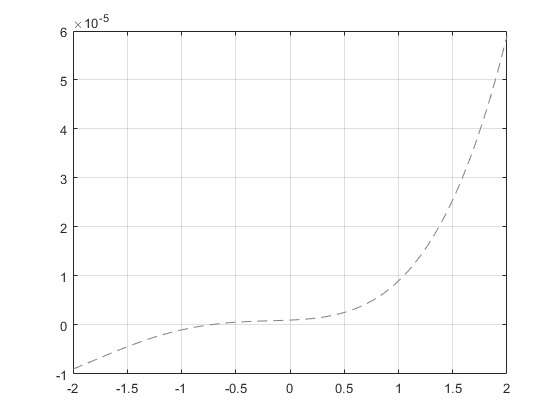

% Przypuśćmy że nasza funkcja interpolowana to wielomian stopnia 5 np.
wsp_oryg=[1 4 2 1 1 1]*1e-6;
xx=linspace(-2,2,401);
yy=polyval(wsp_oryg, xx);

plot(xx,yy,'--', 'Color',[0.5 0.5 0.5]); grid on;

% Będziemy teraz robić 3 interpolacje przy pomocy baz funkcji - naturalnej,
% Lagrange'a i Newtona. Zaczniemy od małego rozmiaru układu równań (małej
% ilości punktów) i zwiększać ją obserwując jak się zachowuje wynik
% interpolacji

for i=[3:2:101]
    
    x_nodes = linspace(min(xx), max(xx),i);
    y_nodes = polyval(wsp_oryg, x_nodes);
    
    % Interpolacja baza naturalną
    warning('off')
    [xx_base,yy_base] = BaseInterpol(x_nodes,y_nodes);
    
    % Interpolacja Lagrange'a
    [xx_lagrange,yy_lagrange] = LagrangeInterpol(x_nodes,y_nodes);
    
    % Interpolacja Newtona
    [xx_newton,yy_newton] = NewtonInterpol(x_nodes,y_nodes);
    
    hold off; semilogy(xx,yy,'--', 'Color',[0.5 0.5 0.5]); grid on;hold on;
    semilogy(x_nodes, abs(y_nodes), 'ob');
    semilogy(xx_base, abs(yy_base), 'r');
    semilogy(xx_lagrange, abs(yy_lagrange), 'b');
    semilogy(xx_newton, abs(yy_newton), 'g'); title("k="+num2str(i));
    pause(0.5);
    
end

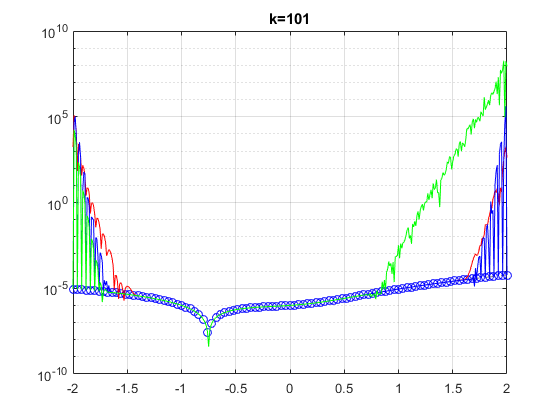

warning('on'); hold off;

Zwróć uwagę, że widoczne różnice widać dopiero przy stosunkowo wysokich stopniach wielomianów interpolujących (dużej ilości punktów). 

**Z powodów, które poznamy później zazwyczaj nie robimy interpolacji pojedynczym wielomianem jeżeli mamy bardzo dużo punktów. Dlatego te metody są równoważne i w zaimplementowanych bibliotekach można znaleźć każdą z nich. Należy jednak pamiętać że wszystkie te implementacje niejawnie zakładają, że nie będziemy za ich pomocą robić interpolacji opartej o wiele punktów (jako regułę kciuka przyjmuje się stopień max 4 - 6, najczęściej 3).**

To kiedy wystąpią problemy z odwzorowaniem zależą nie tylko od budowy układu równań, ale również od tego jakie właściwości ma funkcja oryginalna i jak rozłożone są węzły. W naszym przykładzie obserwujemy wszystkie te błędy choć funkcja dobrana jest w taki sposób, aby ich wpływ był zminimalizowany. Również we wszystkich interpolacjach te parametry są takie same, więc widoczne różnice wynikają właśnie ze sposobu definiowania macierzy układu równań.

Spróbuj pozmieniać funkcję interpolowaną i zaobserwuj jak wpływa to na osiągany wynik.

**WYKROZYSTYWANE FUNKCJE**

function [xx,sum] = LagrangeInterpol(x,y)
xStart = x(1);
xEnd = x(end);
xx = xStart:0.01:xEnd;
k = length(xx);
sum = 0;
for j = 1:length(y)
    pr = 1;
    for i = 1:length(x)
        if i~=j
            pr = pr.*(xx(1:k)-x(i))./(x(j)-x(i));
        end
    end
    prod = y(j)*pr;
    sum = sum + prod;
end
end

function [xx,sum] = BaseInterpol(x,y)
xStart = x(1);
xEnd = x(end);
xx = xStart:0.01:xEnd;
k = length(xx);
sum = 0;
wsp=polyfit(x,y,numel(x)-1);
sum=polyval(wsp,xx);
end

function [x,sum] =  NewtonInterpol(xx,f)
    xStart = xx(1);
    xEnd = xx(end);
    x = xStart:0.01:xEnd;
    n = length(xx);
    d=zeros(n);
    for k = 1 : n - 1
        d(k, 1) = (f(k+1) - f(k))/(xx(k+1) - xx(k));
    end
    for j = 2 : n - 1
        for k = 1 : n - j
            d(k, j) = (d(k+1, j - 1) - d(k, j - 1))/(xx(k+j) - xx(k));
        end
    end
    d=[xx' f' d];
    p1=d(1,2);
    s=1;
    for i=2:n
        s=s.*(x-xx(i-1));
        p1=p1+d(1,i+1).*s;
    end
    sum=p1;
end
